# Supplementary figure 1: How to construct spatial dependent plasticity function

### Fig A: fit $f_P$ and $f_D$ for different velocities

Manuel fit the parameter of potentiation and depotentiation function to the biophysical model

exp: 9-6

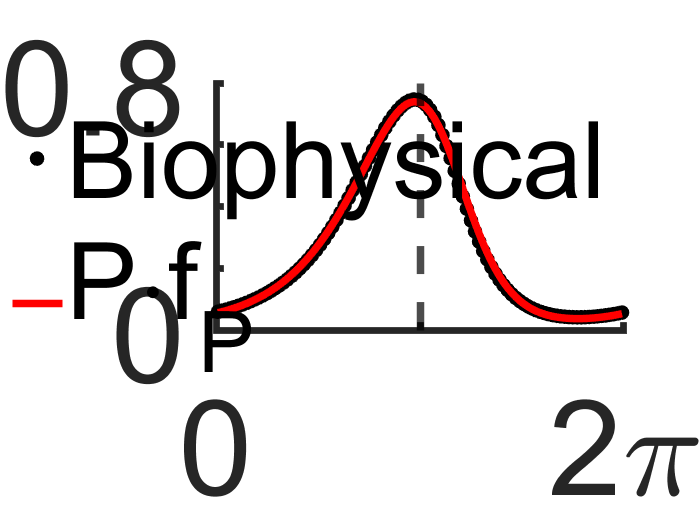

clear; clc
L = 187;        init_weight = 0;        n_ca3 = 100;
inductions = [1, L/2];

velocity = 20;
%velocity = 35;
[synaptic_weight_map, list_pot_map, list_dep_map, ca3_peak_locations_map] = Sim_CA3CA1_map(velocity, inductions, init_weight, L, n_ca3);
[synaptic_weight, list_pot, list_dep, ca3_peak_locations] = Sim_CA3CA1_Romani(velocity, inductions, init_weight, L, n_ca3);

i = 1;
pot_r = list_pot(i, :);
pot_m = list_pot_map(i, :);
dep_r = list_dep(i, :);
dep_m = list_dep_map(i, :);

ind_pos = inductions(inductions(:, 1) == 1, 2);
phase_map = ca3_peak_locations_map / L * 2*pi;
phase = ca3_peak_locations /  L * 2*pi;
phase_ind = ind_pos /  L * 2*pi;  
figure
plot(phase, pot_r, ".k" , "MarkerSize", 30)
hold on
plot(phase_map, pot_m, "-r", "LineWidth", 4.5)
xline(phase_ind, "--k", "LineWidth", 4.5)
if velocity == 20
legend({"Biophysical", "P\cdotf_P"}, 'location', 'northeast')
legend boxoff
hold off
end
box off
ylim([0, 0.8])
yticks([0, 0.2, 0.4, 0.6, 0.8])
yticklabels([0, "", "", "", 0.8])
xlim([0, 2*pi])
xticks([0, pi, 2*pi])
xticklabels([0, " ", "2\pi"])
fig_config(80)

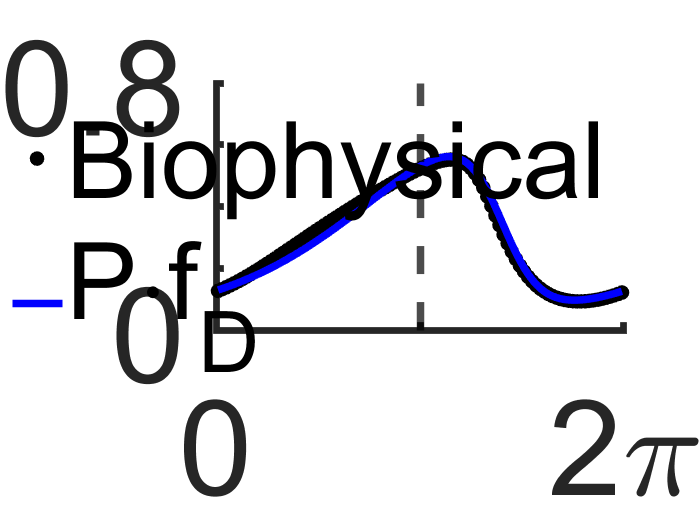


figure
plot(phase, dep_r, ".k" , "MarkerSize", 30)
hold on
plot(phase_map, dep_m, "-b", "LineWidth", 4.5)
xline(phase_ind, "--k", "LineWidth", 4.5)
if velocity == 20
legend({"Biophysical", "P\cdotf_D"}, 'location', 'northeast')
legend boxoff
end
hold off
box off
ylim([0, 0.8])
yticks([0, 0.2, 0.4, 0.6, 0.8])
yticklabels([0, "", "", "", 0.8])
xlim([0, 2*pi])
xticks([0, pi, 2*pi])
xticklabels([0, " ", "2\pi"])
fig_config(80)

### Figure B-C: Simulations using different induction protocols shouw 1D map can match the results of biophysical model

Repetitive induction on same position 5 times

exp 9-6

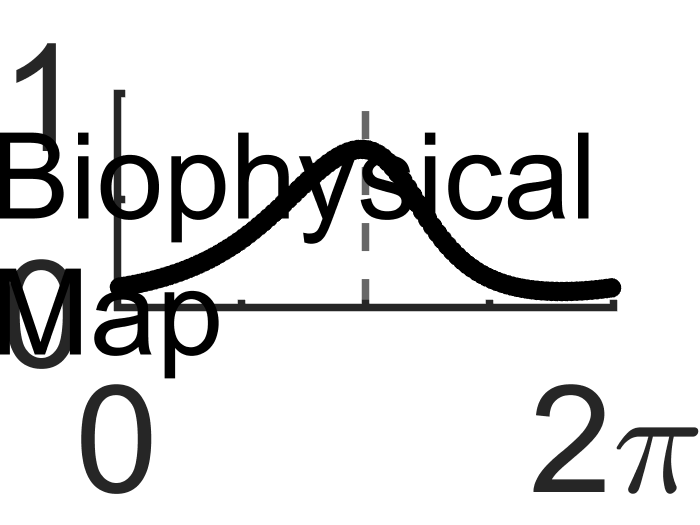

clear; clc
L = 187;        init_weight = 0;        n_ca3 = 100;
inductions = [[1:5]' ones(5, 1) * L /2];
velocity = 25;
[synaptic_weight_map, list_pot_map, list_dep_map, ca3_peak_locations_map] = Sim_CA3CA1_map(velocity, inductions, init_weight, L, n_ca3);
[synaptic_weight, list_pot, list_dep, ca3_peak_locations] = Sim_CA3CA1_Romani(velocity, inductions, init_weight, L, n_ca3);

figure
lap_1 = inductions(1, 1);
ind_1 = inductions(1, 2);
weight_R = synaptic_weight(lap_1 + 1, :);
weight_M = synaptic_weight_map(lap_1 + 1, :);
plot(ca3_peak_locations, weight_R, ".k", "MarkerSize", 40)
hold on
box off
plot(ca3_peak_locations_map, weight_M, "-k", "LineWidth", 4.5)
hold off
xline(ind_1, "--", "LineWidth", 4.5)
xlim([0, L])
legend boxoff
xticks([0, 187/4, 187/2, 187*3/4, 187])
xticklabels(["0", "", "", "", "2\pi"])
ylim([0, 1])
yticks([0, 0.5, 1])
yticklabels([0, "", 1])
legend({"Biophysical", "Map"})
fig_config(90)

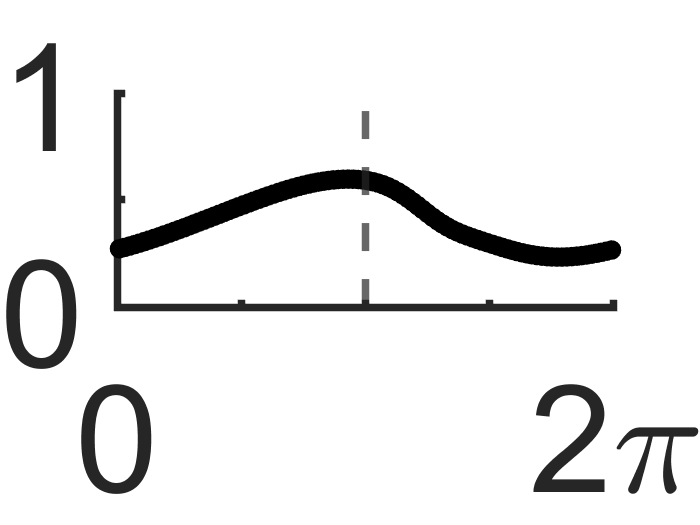



% second
lap_2 = inductions(5, 1);
ind_2 = inductions(5, 2);
weight_R = synaptic_weight(lap_2 + 1, :);
weight_M = synaptic_weight_map(lap_2 + 1, :);

plot(ca3_peak_locations, weight_R, ".k", "MarkerSize", 40)
hold on
box off
plot(ca3_peak_locations_map, weight_M, "-k", "LineWidth", 4.5)
xline(ind_2, "--", "LineWidth", 4.5)
hold off
xlim([0, L])
xticks([0, 187/4, 187/2, 187*3/4, 187])
xticklabels(["0", "", "", "", "2\pi"])
ylim([0, 1])
yticks([0, 0.5, 1])
yticklabels([0, "", 1])
fig_config(90)

Double induction in a single lap.

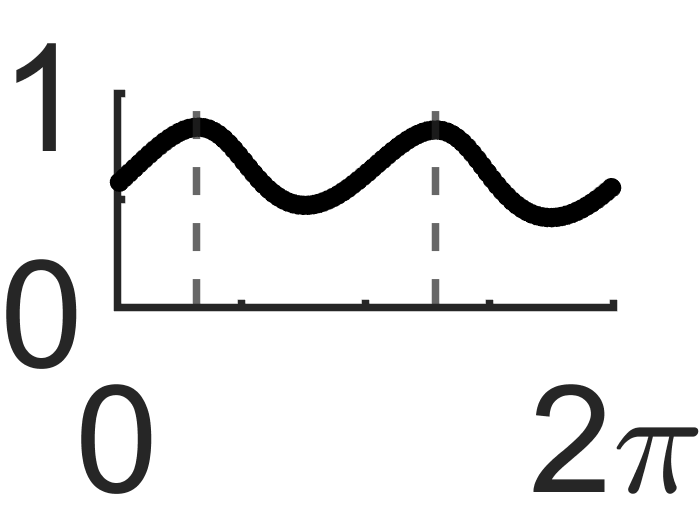

inductions = [1, 30; 1, 120; 2, L/ 2];

[synaptic_weight_map, list_pot_map, list_dep_map, ca3_peak_locations_map] = Sim_CA3CA1_map(velocity, inductions, init_weight, L, n_ca3);
[synaptic_weight, list_pot, list_dep, ca3_peak_locations] = Sim_CA3CA1_Romani(velocity, inductions, init_weight, L, n_ca3);

lap_1 = inductions(1, 1);
ind_1 = inductions(1, 2);
ind_2 = inductions(2, 2);
weight_R = synaptic_weight(lap_1 + 1, :);
weight_M = synaptic_weight_map(lap_1 + 1, :);
plot(ca3_peak_locations, weight_R, ".k", "MarkerSize", 40)
hold on
box off
plot(ca3_peak_locations_map, weight_M, "-k", "LineWidth", 4.5)
hold off
xline(ind_1, "--", "LineWidth", 4.5)
xline(ind_2, "--", "LineWidth", 4.5)
xlim([0, L])
%legend boxoff
xticks([0, 187/4, 187/2, 187*3/4, 187])
xticklabels(["0", "", "", "", "2\pi"])
ylim([0, 1])
yticks([0, 0.5, 1])
yticklabels([0, "", 1])
%legend({"Biophysical", "Map", "Plateau"})
fig_config(90)

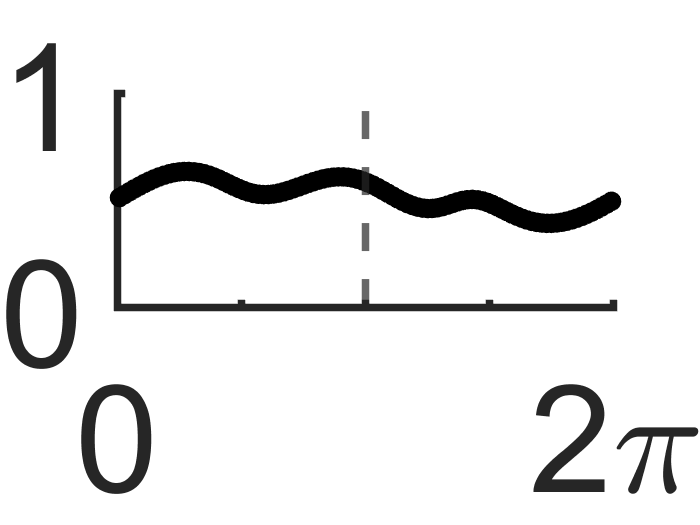


% second
lap_2 = inductions(3, 1);
ind_2 = inductions(3, 2);
weight_R = synaptic_weight(lap_2 + 1, :);
weight_M = synaptic_weight_map(lap_2 + 1, :);

plot(ca3_peak_locations, weight_R, ".k", "MarkerSize", 40)
hold on
box off
plot(ca3_peak_locations_map, weight_M, "-k", "LineWidth", 4.5)
xline(ind_2, "--", "LineWidth", 4.5)
hold off
xlim([0, L])
xticks([0, 187/4, 187/2, 187*3/4, 187])
xticklabels(["0", "", "", "", "2\pi"])
ylim([0, 1])
yticks([0, 0.5, 1])
yticklabels([0, "", 1])
fig_config(90)